# Bernstein-Vazirani Algorithm

This example shows an application of the Bernstein-Varizani Algorithm [1] in order to obtain a linear speedup in a specific problem with regards to a classical approach. First we'll explain the problem we want to solve, then we are gonna propose a classical solution, and lastly a quantum solution using the Bernstein-Vazirani algorithm.

## The Problem

Let $f:{\left\lbrace 0,1\right\rbrace }^n \to \left\lbrace 0,1\right\rbrace$be a function of the form:


$$f\left(x\right)=s\cdot x\;\;\;\;\textrm{mod2}$$


where $x\in {\left\lbrace 0,1\right\rbrace }^n \;$is an n-bit input, $s\in {\left\lbrace 0,1\;\right\rbrace }^n \;$is a hidden string of n bits and the operation $s\cdot x$ denotes the dot product modulo 2 defined as:


$$s\cdot x=s_0 x_0 \oplus s_1 x_1 \oplus \cdots \oplus s_{n-1} x_{n-1}$$


where $\oplus$ is a bitwise XOR.

find $s$.

## Classical Solution

with a classical computer the fastest way to find s is to evaluate $f\left(x\right)\;$n time with input values $x=2^i$ for each $i\in \left\lbrace 0,1,\;\cdots \;,n\;-1\;\right\rbrace$:


$$\begin{array}{l}
f\left\lbrace 100\cdots 0_n \right\rbrace =s_1 \\
f\left\lbrace 010\cdots 0_n \right\rbrace =s_2 \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\vdots \;\\
f\left\lbrace 000\cdots 1_n \right\rbrace =s_n 
\end{array}$$


making the complexity of the algorithm obviusly $O\left(n\right)$.

let's see an example with a 5 digit input

## Solving Using Bernstein-Vazirani Quantum Algorithm

#### Initialization

Using the Bernstein-Vazirani algorithm will allow us to obtain a linear speedup and solve the probelem with only one query to the oracle $U_f$.

The quantum circuit must have a register with n qubits to rappresent the input values $x$ and a single qubit register to store the result $f\left(x\right)$, we are gonna set the initial state of the circuit this way:


$$|\psi_o \rangle =|0\rangle^{\otimes n} \;|1\rangle$$


#### Explaining the Circuit

after applying an Hadamard transorm to both the input register and the result register the state becomes


$$|\psi_1 \rangle =\sum_{x\in {\left\lbrace 0,1\right\rbrace }^n }^{2^n -1} \frac{|x\rangle }{\sqrt{2^n }}\;\left(\frac{|0\rangle -|1\rangle }{\sqrt{2}}\right)$$


the input register is now a superposition of all values and the result register is in a superposition of 0 and 1. next the function $f$ is evaluated by the oracle $U_f :|x,y\rangle \to |x,y\oplus f\left(x\right)\rangle$ giving


$$|\psi_2 \rangle =\sum_x^{2^n -1} \frac{{\left(-1\right)}^{f\left(x\right)} |x\rangle }{\sqrt{2^n }}\;\left(\frac{|0\rangle -|1\rangle }{\sqrt{2}}\right)$$


it is clear from this formula that now the information about $f\left(x\right)\;$is stored in the amplitude. Finally after applying anothe Hadamard transform on the input register we get the form

$|\psi_3 \rangle =\sum_z^{2^n -1} \sum_x^{2^n -1} \frac{{\left(-1\right)}^{x\cdot z+f\left(x\right)} |z\rangle }{2^n }$$\left(\frac{|0\rangle -|1\rangle }{\sqrt{2}}\right)$= $\sum_z^{2^n -1} \sum_x^{2^n -1} \frac{{\left(-1\right)}^{x\cdot z+x\cdot s} |z\rangle }{2^n }$$\left(\frac{|0\rangle -|1\rangle }{\sqrt{2}}\right)$

now let's analyze just the term $\sum_x \frac{{\left(-1\right)}^{x\cdot z+x\cdot s} |z\rangle }{2^n }$, $x\cdot z+x\cdot s=0$  if and only if $z=s$, so $|\psi_3 \rangle =|s\rangle$ with probability of mesurement 1, while each and every other combination having $x\cdot z+x\cdot s=0$ has a probability to be mesured equal to zero. So with one single query to the oracle we obtained the secret string $s$. 

Here you can see the oracle in it's whole [2]:

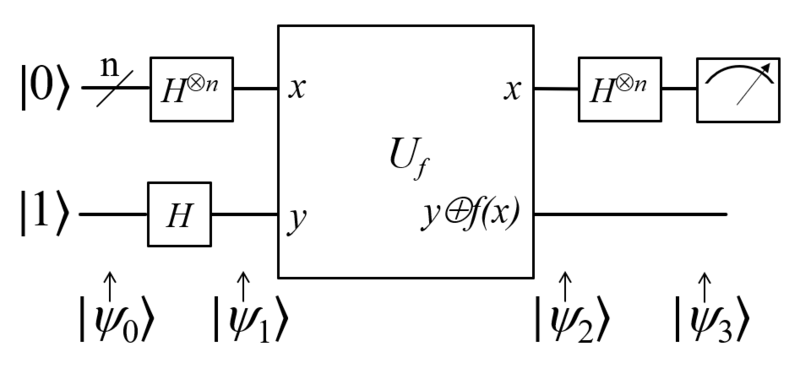

#### Building the Circuit

now let's implement our circuit with an oracle specific to $s$ and test it

% fai funzione che gli passi il numero di bit e S e lei ti calcola s (si è stupidissima come cosa)

function qc = BVcircuit(numQubits, secret_string)
    totalQubits = numQubits + 1;

    gates = [];

    % apply Hadamard gate on each qubit
    for n = 1:totalQubits
        gates = [gates, hGate(n)];
    end

    % create oracle
    for(n = 1:totalQubits-1)
        if secret_string(n) == '1'
            gates = [gates, cxGate(n, totalQubits)];
        end
    end

    % apply Hadamard on the input register
    for n = 1:numQubits
        gates = [gates, hGate(n)];
    end

    qc = quantumCircuit(gates, numQubits + 1); 
    
end 


Select the specific secret string $s$ and the function will automatically implement the amount of qubits required

secret_string = char("1010111");

Keep in mind that $s$ will not be use to fine the result, but just to implement it's specific oracle!

numQubits = length(secret_string);

qc = BVcircuit(numQubits, secret_string);

now let's plot the circuit

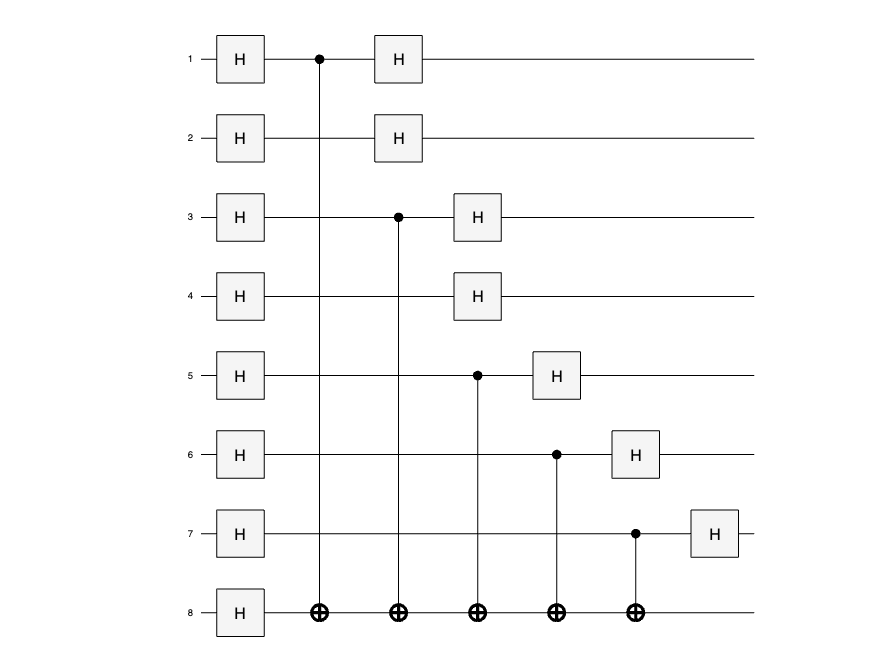

plot(qc);

finally, let's simulate the circuit and see the results

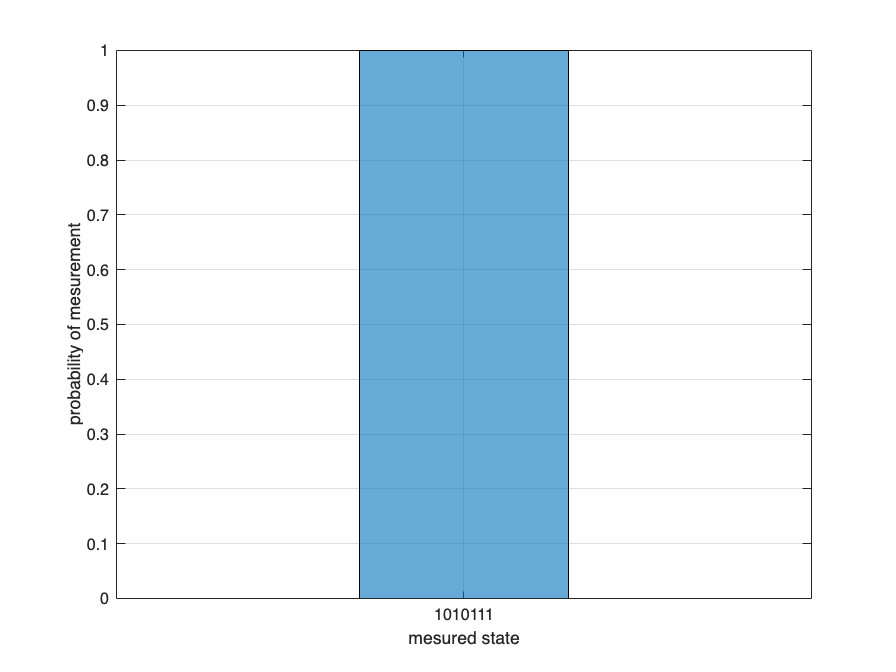

inputString = ['0' * ones(1, numQubits), '1'];
s = simulate(qc, inputString);

histogram(s, 1:numQubits);
xlabel('mesured state');
ylabel('probability of mesurement');
grid on;

as expected we mesure the sting $s$ with probability 1 with only one query to the oracle ($O\left(1\right)$), offering a linear speedup compared to the classical solution ($O\left(n\right)$)

## References

[1] E. Bernstein & U. Vazirani, “Quantum Complexity Theory”

[2] Michael A. Nielsen, Isaac L. Chuang "Quantum Computation and Quantum Information"